# Metoda BTCS


clear,clc,close all
L=1;%in mm
tk=600;%in s
D=0.0000611;
%%
dx=0.05;
dt=20;
x=0:dx:L;
t=0:dt:tk;
x_val=length(x);
x_end=max(x);
t_val=length(t);
r=D*dt/dx^2;
%%BC
t0_bc=sin(2*pi*x);
t0_bc=@(x) sin(2*pi*x)

t0_bc = function_handle with value:
    @(x)sin(2*pi*x)


%t0_bc=@(x) x.^2-4.*x;
x0_bc=0;
xe_bc=0;
%% mapping
for i=1:t_val;
    for j=1:x_val;
        if x(j)==0
            A(i,j)={[[t(i)] [x(j)]  [x0_bc]]};
        elseif x(j)==x_end
            A(i,j)={[[t(i)] [x(j)]  [xe_bc]]}; 
        elseif t(i)==0
            A(i,j)={[[t(i)] [x(j)]  [t0_bc(x(j))]]};
        else
            A(i,j)={[[t(i)] [x(j)]  [NaN]]};
        end
    end
end
for i=2:t_val
    B=(2+1/r)*eye(x_val-2)+diag((-1)*ones(1,x_val-3),1)+diag((-1)*ones(1,x_val-3),-1);
        for j=2:x_val-1
            bc(j-1,1)=1/r*A{i-1,j}(3);
        end
        bc(1)=bc(1)+A{i,1}(3);
        bc(length(bc))=bc(length(bc))+A{i,x_val}(3);
        val=inv(B)*bc;
        for k=1:length(val)
            A{i,k+1}(3)=val(k);
        end
end
o=1;
for i=2:t_val
    for j=2:x_val-1
        if isempty(A{i,j})==0
            t_final(o,1)=A{i,j}(1);
            x_final(o,1)=A{i,j}(2);
            epsilon_final(o,1)=A{i,j}(3);
            o=o+1;
        end
    end
end
for i=2:t_val
    for j=2:x_val-1
        eps_mesh(i-1,j-1)=A{i,j}(3);
    end
end
ttable=table([t_final],[x_final],[epsilon_final])

ttable = 570×3 table
    t_final    x_final       epsilon_final    
    _______    _______    ____________________

      20        0.05         0.294906556239914
      20         0.1         0.560945604020267
      20        0.15         0.772075387741277
      20         0.2         0.907629053144631
      20        0.25         0.954337663002726
      20         0.3         0.907629053144631
      20        0.35         0.772075387741277
      20         0.4         0.560945604020267
      20        0.45         0.294906556239914
      20         0.5      4.26697622799239e-17
      20        0.55        -0.294906556239914
      20         0.6        -0.560945604020266
      20        0.65        -0.772075387741277
      20         0.7        -0.907629053144631
      20        0.75        -0.954337663002726
      20         0.8        -0.907629053144631


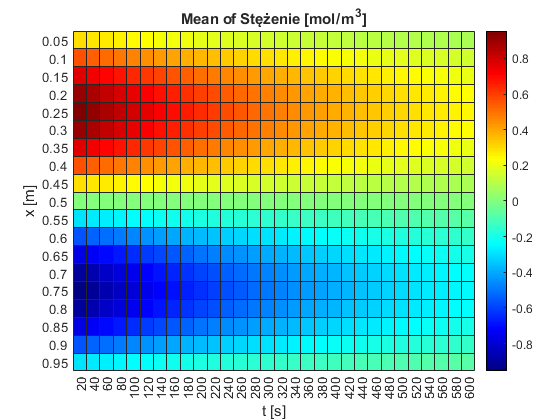

h =   HeatmapChart (Mean of Stężenie [{mol}/{m{^3}}]) with properties:

      SourceTable: [570×3 table]
        XVariable: 't [s]'
        YVariable: 'x [m]'
    ColorVariable: 'Stężenie [{mol}/{m{^3}}]'
      ColorMethod: 'mean'

  Show all properties


ttable = renamevars(ttable,["t_final","x_final","epsilon_final"] ...
    ,["t [s]","x [m]","Stężenie [{mol}/{m{^3}}]"]);
h = heatmap(ttable,'t [s]','x [m]','ColorVariable', ...
    'Stężenie [{mol}/{m{^3}}]','Colormap',jet)

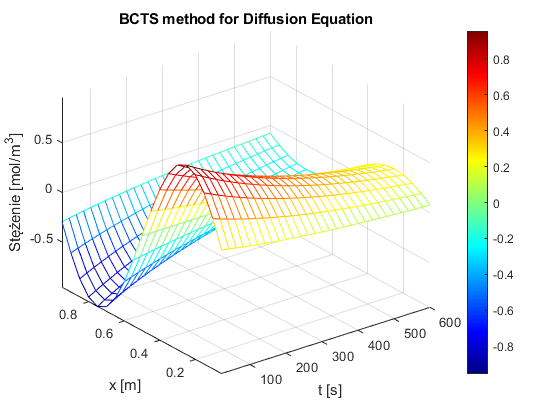

mesh(t(2:end),x(2:end-1),transpose(eps_mesh))
colormap(jet)
colorbar
axis tight
title('BCTS method for Diffusion Equation')
xlabel('t [s]') 
ylabel('x [m]')
zlabel('Stężenie [{mol}/{m{^3}}]')

o=1;
for i=2:length(t)
    for j=2:length(x)-1
        ana(i-1,j-1)=sin(2*pi*x(j))*exp(-4*pi^2*D*t(i));
        ana_final(o,1)=sin(2*pi*x(j))*exp(-4*pi^2*D*t(i));
        o=o+1;
    end
end
atable=table([t_final],[x_final],[ana_final])

atable = 570×3 table
    t_final    x_final         ana_final      
    _______    _______    ____________________

      20        0.05         0.294463084959565
      20         0.1         0.560102071518336
      20        0.15          0.77091436485629
      20         0.2         0.906264188885892
      20        0.25         0.952902559793449
      20         0.3         0.906264188885892
      20        0.35          0.77091436485629
      20         0.4         0.560102071518336
      20        0.45         0.294463084959565
      20         0.5      1.16696906975037e-16
      20        0.55        -0.294463084959566
      20         0.6        -0.560102071518336
      20        0.65        -0.770914364856289
      20         0.7        -0.906264188885892
      20        0.75        -0.952902559793449
      20         0.8        -0.906264188885892


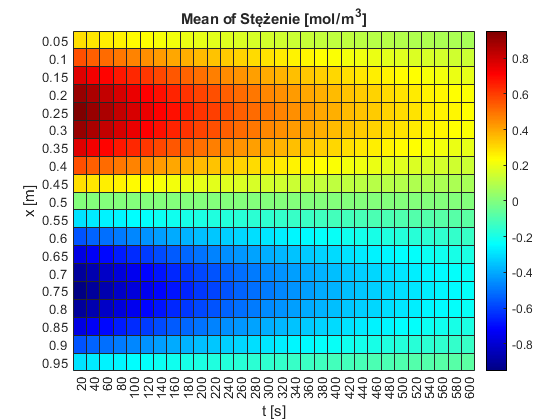

h2 =   HeatmapChart (Mean of Stężenie [{mol}/{m{^3}}]) with properties:

      SourceTable: [570×3 table]
        XVariable: 't [s]'
        YVariable: 'x [m]'
    ColorVariable: 'Stężenie [{mol}/{m{^3}}]'
      ColorMethod: 'mean'

  Show all properties


atable = renamevars(atable,["t_final","x_final","ana_final"], ...
    ["t [s]","x [m]","Stężenie [{mol}/{m{^3}}]"]);
h2 = heatmap(atable,'t [s]','x [m]','ColorVariable', ...
    'Stężenie [{mol}/{m{^3}}]','Colormap',jet)

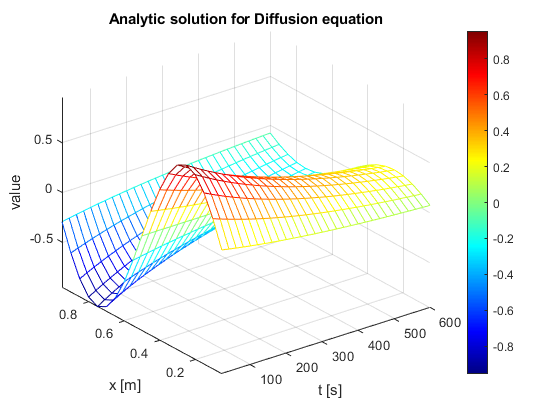

mesh(t(2:end),x(2:end-1),transpose(ana))
colormap(jet)
axis tight
xlabel('t [s]') 
ylabel('x [m]')
zlabel('value')
title('Analytic solution for Diffusion equation')
colormap(jet)
colorbar

error=abs(eps_mesh-ana);
mesh(t(2:end),x(2:end-1),transpose(error))
colormap(jet)
axis tight
xlabel('t [s]') 
ylabel('x [m]')
zlabel('Wartość błędu')
name=sprintf('Błąd metody BTCS, dx= %2.3f,dt= %2.0f',dx,dt)

name = 'Błąd metody BTCS, dx= 0.050,dt= 20'

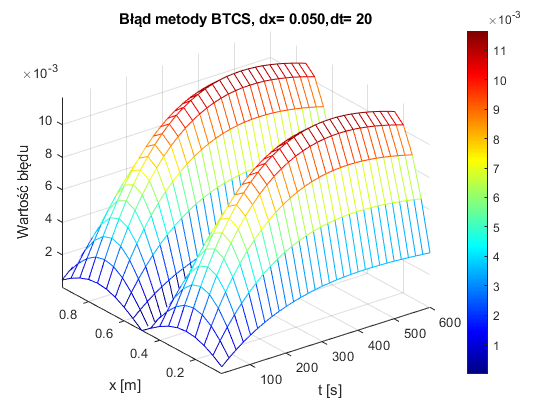

title(name)
colormap(jet)
colorbar

error_norm2=norm(error,'fro')

error_norm2 =    0.171035813432452
